clear ur
ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e') %Conectamos ROS de matlab con el cobot

ur =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.22.0.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     1.5708   -1.5708    1.5708   -1.5708   -1.5708         0


defase_Robot = pi;
%realSense = realsenseSubscriberSO_ARM; %-----------ACTIVAR
% Carga la tabla desde el archivo MAT
load('mi_tabla.mat','TablaDatos');
%% Carga el detector


% d = load("detector_hotel1.mat");
detector = d.detector

detector =   yolov4ObjectDetector with properties:

             Network: [1×1 dlnetwork]
         AnchorBoxes: {2×1 cell}
          ClassNames: {5×1 cell}
           InputSize: [416 416 3]
    PredictedBoxType: 'axis-aligned'
           ModelName: 'tiny-yolov4-coco'


%%Inicia la cámara
realSense = realsenseSubscriberSO_ARM2;

### ***SECUENCIA 1 (GRIS)***

for i=1:1:9
    actuateGripper(ur,'release')
    %Secuencia de colocarse sobre el objeto e ir por el
    n = 0.300;
    coci = car2pol(0.05,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    pause(2.5)
    for e=1:1:4
        coci = car2pol(TablaDatos.X(i),TablaDatos.Y(i),TablaDatos.Z(i)+n);
        jointAngles = MoverRobot(coci,TablaDatos.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
        pause(0.25)
        n = n-0.100;
    end

    %Cierra el gripper
    actuateGripper(ur,'grip');
    pause(3);
    if ismember(TablaDatos.Etiqueta(i),["Azul", "Morado", "Verde","Rojo"])
        coci = car2pol(0.1,0.35,0.35);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        jointAngles=sube(coci,jointAngles,defase_Robot,ur);
        [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
        %Toma de fotos para analisis de color
        %
        %
    end
    %Va al bote de basura
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)

    if i>=5 && i<=6
        coci = car2pol(0.18,0.3,0.335);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
    end 

    [jointAngles,~]=bote(0,defase_Robot,jointAngles,ur,TablaDatos.Cesto(i));
    pause(2.5);
end

condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q =    -0.4747
   -1.9545
    1.7548
   -1.3711
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.9731
    2.0220
   -1.6197
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.9205
    2.2513
   -1.9016
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.7617
    2.4377
   -2.2468
   -1.5708
   -0.6892


condicion = logical
   1


q =     0.9176
   -1.9308
    1.7974
   -1.4375
   -1.5708
   -0.3741


condicion = logical
   1


q =     0.9176
   -1.9395
    1.9307
   -1.5620
   -1.5708
    1.1959


condicion = logical
   1


q =     1.4205
   -1.4402
    1.3674
   -1.4980
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.4274
    1.6088
   -1.7522
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.3554
    1.7904
   -2.0058
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.2246
    1.9154
   -2.2616
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.4413
    1.4962
   -1.6257
   -1.5708
    1.3314


condicion = logical
   1


q =     0.6395
   -1.9721
    1.8605
   -1.4593
   -1.5708
   -0.3901


condicion = 1×2 logical array
   1   0


q =     1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q =     2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612


condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q =    -0.4747
   -1.9647
    1.8254
   -1.4315
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.9677
    2.0829
   -1.6859
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.8926
    2.3024
   -1.9807
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.7000
    2.4755
   -2.3463
   -1.5708
   -0.6892


condicion = logical
   1


q =     0.9176
   -1.9308
    1.7974
   -1.4375
   -1.5708
   -0.3741


condicion = logical
   1


q =     0.9176
   -1.9395
    1.9307
   -1.5620
   -1.5708
    1.1959


condicion = logical
   1


q =     1.4205
   -1.4402
    1.3674
   -1.4980
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.4274
    1.6088
   -1.7522
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.3554
    1.7904
   -2.0058
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.2246
    1.9154
   -2.2616
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.4413
    1.4962
   -1.6257
   -1.5708
    1.3314


condicion = logical
   1


q =     0.6395
   -1.9721
    1.8605
   -1.4593
   -1.5708
   -0.3901


condicion = 1×2 logical array
   1   0


q =     1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q =     2.7763
   -1.5112
    1.5733
   -1.6329
   -1.5708
    1.3182


condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q =    -0.4747
   -1.9713
    1.8934
   -1.4929
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.9575
    2.1414
   -1.7547
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.8573
    2.3508
   -2.0643
   -1.5708
   -0.6892


condicion = logical
   1


q =    -0.4747
   -1.6283
    2.5088
   -2.4512
   -1.5708
   -0.6892


condicion = logical
   1


q =     0.9176
   -1.9308
    1.7974
   -1.4375
   -1.5708
   -0.3741


condicion = logical
   1


q =     0.9176
   -1.9395
    1.9307
   -1.5620
   -1.5708
    1.1959


condicion = logical
   1


q =     1.4205
   -1.4402
    1.3674
   -1.4980
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.4274
    1.6088
   -1.7522
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.3554
    1.7904
   -2.0058
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.2246
    1.9154
   -2.2616
   -1.5708
    1.3314


condicion = logical
   1


q =     1.4205
   -1.4413
    1.4962
   -1.6257
   -1.5708
    1.3314


condicion = logical
   1


q =     0.6395
   -1.9721
    1.8605
   -1.4593
   -1.5708
   -0.3901


condicion = 1×2 logical array
   1   0


q =     1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612



coci = car2pol(0,0.35,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);

condicion = logical
   1


q = 6×1
    1.1801
   -1.9669
    1.8190
   -1.4228
   -1.5708
   -0.3899


### ***SECUENCIA 2 (AMARILLA)***

for i=1:1:3
    actuateGripper(ur,'release')
    %Secuencia de colocarse sobre el objeto e ir por el
    n = 0.300;
    coci = car2pol(0.05,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    pause(2.5)
    for e=1:1:4
        coci = car2pol(TablaDatos.X(i),TablaDatos.Y(i),TablaDatos.Z(i)+n);
        jointAngles = MoverRobot(coci,TablaDatos.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
        pause(0.25)
        n = n-0.100;
    end

    %Cierra el gripper
    actuateGripper(ur,'grip');
    pause(3);
    if ismember(TablaDatos.Etiqueta(i),["Azul", "Morado", "Verde","Rojo"])
        coci = car2pol(0.1,0.35,0.35);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        jointAngles=sube(coci,jointAngles,defase_Robot,ur);
        [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
        %Toma de fotos para analisis de color
        %
        %
    end
    %Va al bote de basura
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)

    if i>=5 && i<=6
        coci = car2pol(0.18,0.3,0.335);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
    end 

    [jointAngles,~]=bote(0,defase_Robot,jointAngles,ur,TablaDatos.Cesto(i));
    pause(2.5);
end

coci = car2pol(0,0.35,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);


i=1;
ab=1;

#### Secuencia zona roja 1

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

condicion = logical
   1


q =     1.0318
   -1.9324
    1.8369
   -1.4753
   -1.5708
   -0.5281


jointAngles =     1.0318   -1.9324    1.8369   -1.4753   -1.5708   -0.5281


H_Actual_Mesa =    -0.0109   -0.9999         0    0.3600
   -0.9999    0.0109         0   -0.0600
         0         0   -1.0000    0.3350
         0         0         0    1.0000


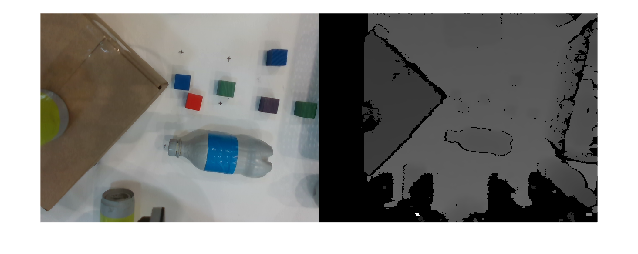


%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')

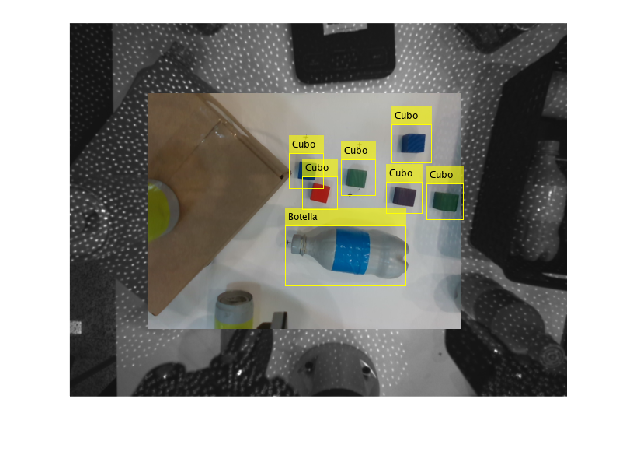

[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)

Cubo


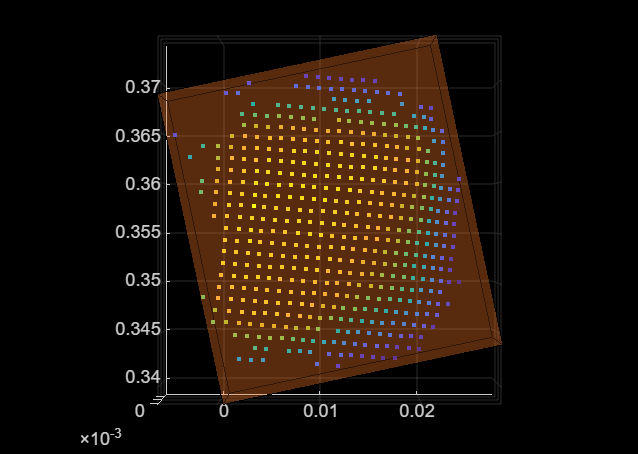

x2 = 0.0110

y2 = 0.3563

z2 = -0.0017

OrientacionObjeto = -1.3614

 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)

Cubo


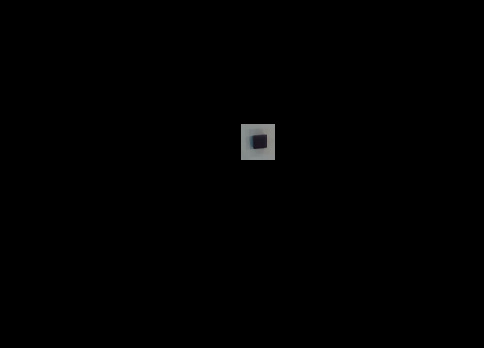

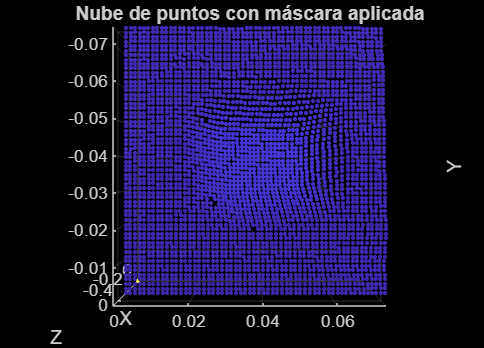

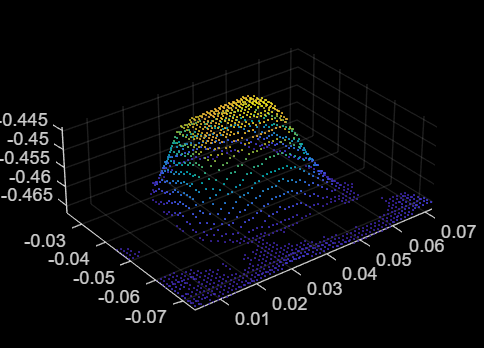

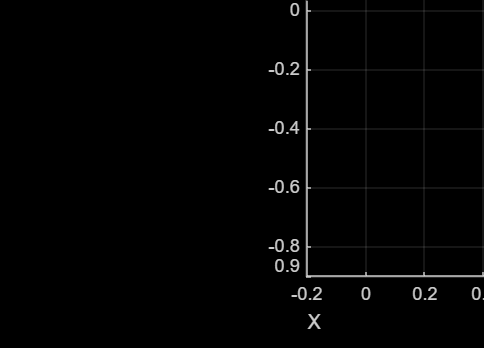

OrientacionObjeto = 1.3439

x2 = 0.4725

y2 = -0.0952

z2 = 0.8905

pause(1)

%%Movimiento a zona aproximada
x = x2; y = y2;

x = -0.0952

y = 0.4225

z = 0.055;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

condicion = 1×2 logical array
   1   0


q =     1.4796
   -1.5069
    2.2635
   -2.3274
   -1.5708
   -0.4671


jointAngles =     1.4796   -1.5069    2.2635   -2.3274   -1.5708   -0.4671


H_Actual_Mesa =     0.3671   -0.9302         0    0.4225
   -0.9302   -0.3671         0    0.0952
         0         0   -1.0000    0.0550
         0         0         0    1.0000


H_captura = H_Actual_Mesa;

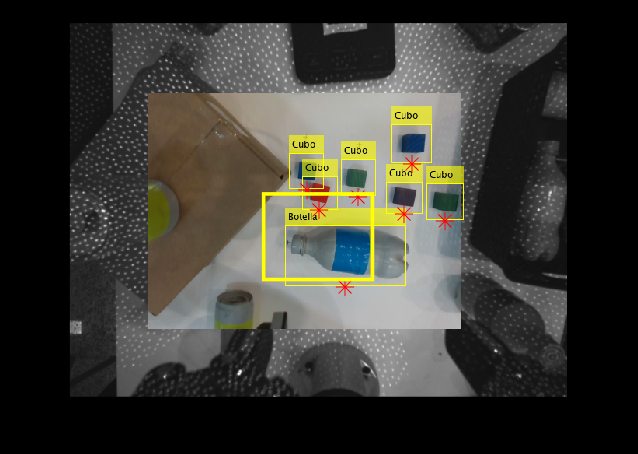

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end

#### Secuencia zona amarilla (2)

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)
 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
pause(1)
%%Movimiento a zona aproximada
x = x2; y = y2;
z = 0.335;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
H_captura = H_Actual_Mesa;

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end

#### Secuencia zona amarilla (3)

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)
 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
pause(1)
%%Movimiento a zona aproximada
x = x2; y = y2;
z = 0.335;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
H_captura = H_Actual_Mesa;

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end

#### Secuencia zona roja 2 (4)

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)
 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
pause(1)
%%Movimiento a zona aproximada
x = x2; y = y2;
z = 0.335;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
H_captura = H_Actual_Mesa;

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end

#### Secuencia zona roja 4 (5)

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)
 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
pause(1)
%%Movimiento a zona aproximada
x = x2; y = y2;
z = 0.335;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
H_captura = H_Actual_Mesa;

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end

#### Secuencia zona roja 4 (5.2) cubo morado

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)
 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
pause(1)
%%Movimiento a zona aproximada
x = x2; y = y2;
z = 0.335;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
H_captura = H_Actual_Mesa;

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end

#### Secuencia zona azul (6)

%%%Movimiento de robot a zona roja 1
%%%Posición de robot
x = 0.06;
y = 0.36;
z = 0.335;
angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)

%%%Toma de fotografías con camara realsense
[rgb, nube, ir]=realSense.step;   %saco las fotos
% [colorImage, orderedPointCloud, irImage]   lo que se pide en la funcion
% guardar_inf(rgb,nube,profd,ir,H_Actual_Mesa,ab)
% ab=ab+1;
imshowpair(rgb,nube(:,:,3),'montage')
[outputImg] = alineado(ir,rgb);
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
imshow(I2)
 if isempty(labels)
        ('Zona limpia u objeto no detectado')
        % break;
 end
    % Selecciona la mejor detección por prioridad
   label2 = string(labels);

m = buscarIndicePrioritario_Brasil(label2);
% m=1;
% H_actual = H_Actual_Mesa  %%quitar comentario
[x2,y2,z2,OrientacionObjeto,label3] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
pause(1)
%%Movimiento a zona aproximada
x = x2; y = y2;
z = 0.335;
angulo_Gripper= OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
H_captura = H_Actual_Mesa;

%%Segunda pasada del algoritmo: dependiendo del algoritmo
[rgb, nube, ir]=realSense.step;   %saco las fotos
[I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     if label3 == "Cubo"
        temp = Centroids(:,1) > 250 & Centroids(:,1) < 390 & Centroids(:,2) > 220 & Centroids(:,2) < 330;
        Centroides = Centroids(temp,:);
        labels(temp)
    else
        temp = Centroids(:,1) > 280 & Centroids(:,1) < 360 & Centroids(:,2) > 310;
        Centroides = Centroids(temp,:);
        labels(temp)
        if isempty(Centroides)
            temp = Centroids(:,1) > 240 & Centroids(:,1) < 400 & Centroids(:,2) > 290;
            Centroides = Centroids(temp,:);
            labels(temp)
        else
        end
     end
[~,m]=max(temp)   %%Obtiene el índice del objeto dentro del recuadro

[x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual)
% Movimiento a posicion final  desfase en x de 0.01
[h_agarre,label1] = altura_agarre_Brasil(label1,z2)
% Movimiento de ajuste hacia abajo
x = x2; y = y2;
z = 0.18;
angulo_Gripper = OrientacionObjeto;
% angulo_Gripper = 1.725; %con respecto al eje principal del cobot c---g 
coci = car2pol(x,y,z);
[jointAngles,H_Actual_Mesa]= MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur)
pause(1)
%%5 CICLO FOR para bajar
    for h = z:-0.005:h_agarre        
        coci = car2pol(x,y,h);
        jointAngles = MoverRobot(coci,angulo_Gripper,defase_Robot,jointAngles,ur); %ur
        pause(0.25)
    end
actuateGripper(ur,'grip')
pause(3);
jointAngles=sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
coci = car2pol(0.18,0.3,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

if label1 == "Cubo"
    % jointAngles=sube(coci,jointAngles,defase_Robot,ur);
    % pause(2.5)
    % coci = car2pol(0.1,0.35,0.35);
    % jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    % pause(2.5)
    [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur);
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)
    coci = car2pol(0.1,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
end

if label1 ~= "Vacío"
[bandera] = bandera_botes_brasil(label1)
[jointAngles,coci]=bote(angulo_Gripper,defase_Robot,jointAngles,ur,bandera)
end